Section One

init();
N=16; %number of samples in time and freq domain
n=0:N-1; %index for freq domain.
T=9; %signal period
Ts=T/N; %sample period
t=0:Ts:T-Ts;
Ts

Ts = 0.5625

ws = ((2*pi)/Ts)

ws = 11.1701

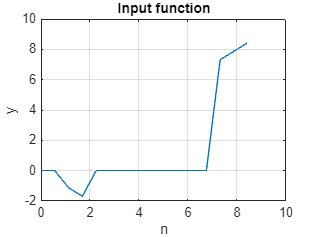


y=zeros(size(t));
t_between_1_and_2=find(t>=1 & t<=2);
y(t_between_1_and_2)=-t(t_between_1_and_2);
t_between_2_and_7=find(t>2 & t<7);
y(t_between_2_and_7)=0;
t_greater_than_7=find(t>= 7 );
y(t_greater_than_7)= t(t_greater_than_7);
make_plot(t,y,'Input function','n','y');

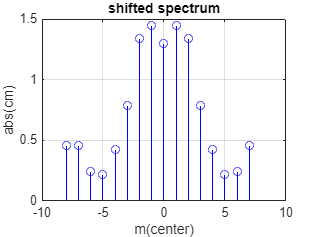

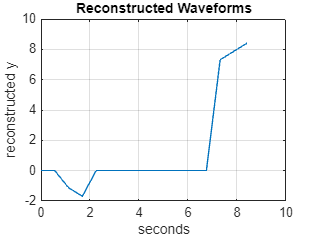


[cm,yy] = fft_ifft(t,n,y,N);

[m_ctr,cm_ctr, yy] = fft_ifft(t,n,y,N);

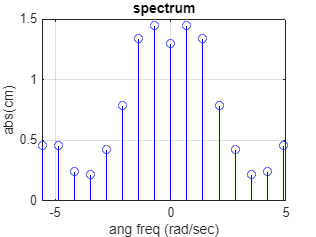

angFreq = m_ctr * 2 * pi / T;
make_stem(angFreq,abs(cm_ctr),'spectrum','ang freq (rad/sec)','abs(cm)');